+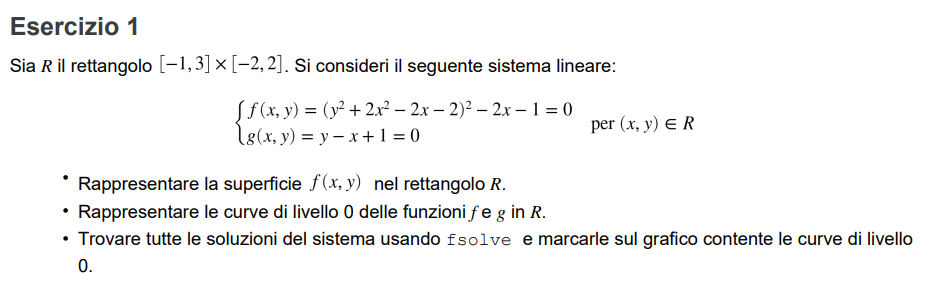

clear all
close all

f = @(x,y) (y.^2+2*x.^2-2*x-2).^2 -2*x-1;
g = @(x,y) y-x+1

g = function_handle with value:
    @(x,y)y-x+1

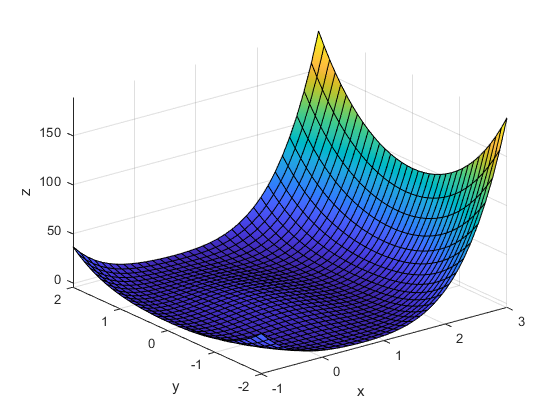

fsurf(f,[-1 3 -2 2])
xlabel x
ylabel y
zlabel z


figure
fcontour(f,[-1 3 -2 2],"LevelList",0)
hold on
fcontour(g,[-1 3 -2 2],"LevelList",0,"LineColor",'b')
xlabel x
ylabel y



guardo dove le due linee di livello si incontrano e uso un punto di partenza vicino

#### creo il sistema delle due funzioni 

F=@(x) [f(x(1),x(2));g(x(1),x(2))];
[zm,fval] = fsolve(F,[0,-1]);


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'or')
[zm,fval] = fsolve(F,[1,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'om')
[zm,fval] = fsolve(F,[2,1]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'og')
[zm,fval] = fsolve(F,[-0.25,-1.25]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


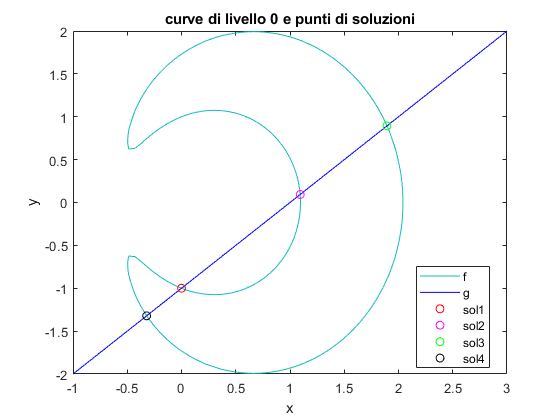

plot(zm(1),zm(2),'ok')
legend("f","g","sol1","sol2","sol3","sol4","Location","best")
title("curve di livello 0 e punti di soluzioni")

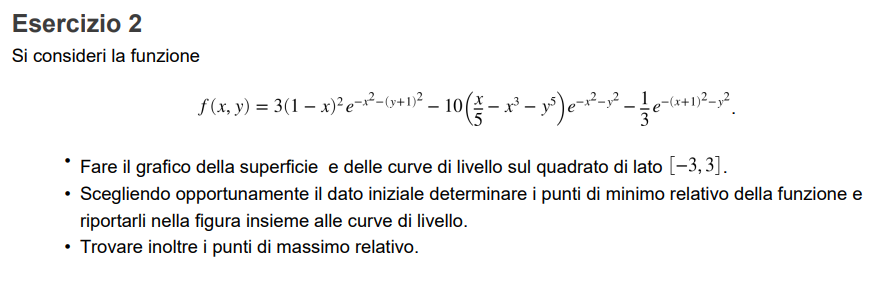

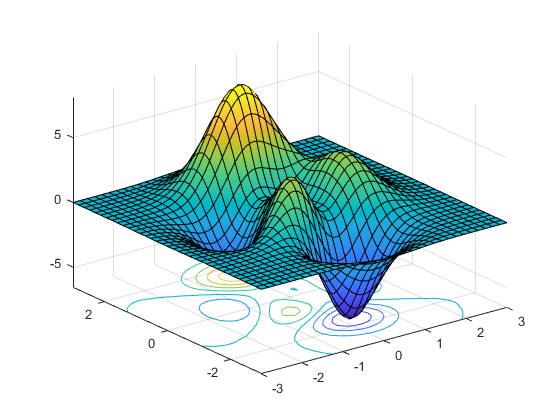

clear all
close all
f = @(x,y) 3*(1-x).^2.*exp(-x.^2-(y+1).^2)-10*(x./5-x.^3-y.^5).*exp(-x.^2-y.^2)-1/3*exp(-(x+1).^2-y.^2);
fsurf(f,[-3 3 -3 3],"ShowContours",'on')

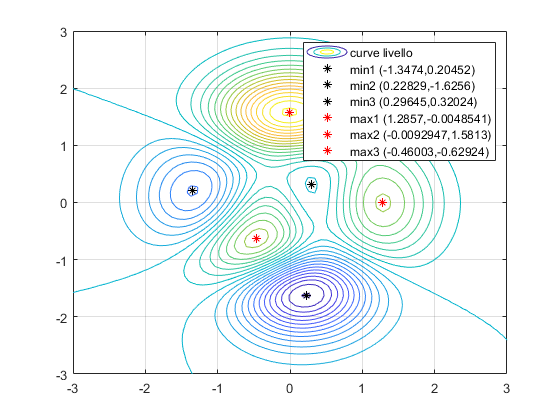

fcontour(f,[-3 3 -3 3],"LevelList",-8:0.5:10)
leg = [];
leg = [leg "curve livello"];
grid on
hold on
F= @(x) f(x(1),x(2));
[sol,fval]=fminsearch(F,[-0.5 ;-0.5]);
plot(sol(1),sol(2),'*k')
leg =[leg "min1 ("+sol(1)+","+sol(2)+")"];
[sol,fval]=fminsearch(F,[0.5 ;-1.5]);
plot(sol(1),sol(2),'*k')
leg =[leg "min2 ("+sol(1)+","+sol(2)+")"];
[sol,fval]=fminsearch(F,[0.5 ;0.5]);
plot(sol(1),sol(2),'*k')
leg =[leg "min3 ("+sol(1)+","+sol(2)+")"];

f = @(x,y) -(3*(1-x).^2.*exp(-x.^2-(y+1).^2)-10*(x./5-x.^3-y.^5).*exp(-x.^2-y.^2)-1/3*exp(-(x+1).^2-y.^2));
F= @(x) f(x(1),x(2));
[sol,fval]=fminsearch(F,[1.5 ;0]);
plot(sol(1),sol(2),'*r')
leg =[leg "max1 ("+sol(1)+","+sol(2)+")"];
[sol,fval]=fminsearch(F,[0 ;2]);
plot(sol(1),sol(2),'*r')
leg =[leg "max2 ("+sol(1)+","+sol(2)+")"];
[sol,fval]=fminsearch(F,[-0.5 ;-0.5]);
plot(sol(1),sol(2),'*r')
leg =[leg "max3 ("+sol(1)+","+sol(2)+")"];

legend(leg)

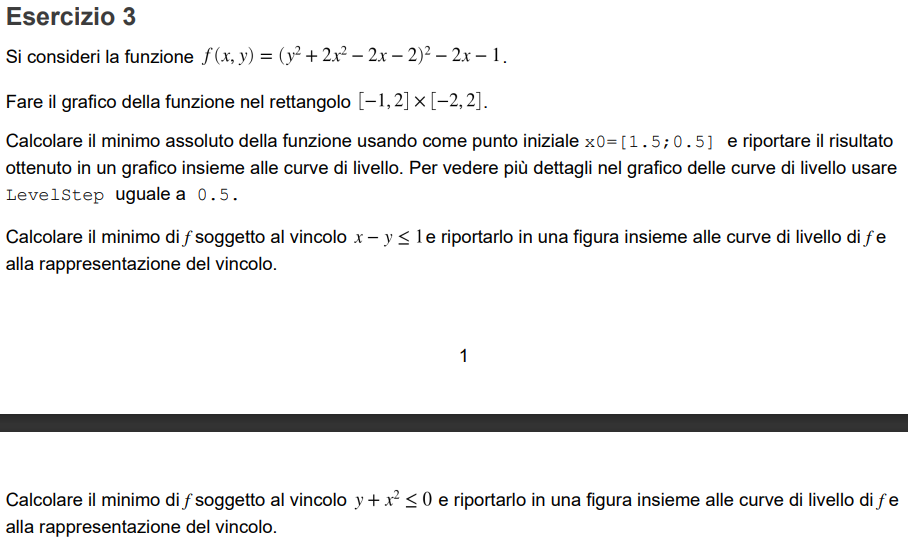

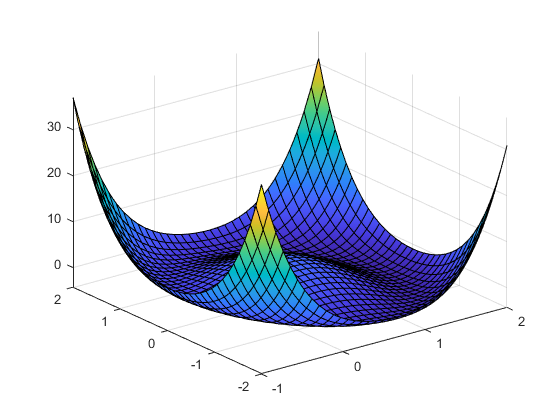

clear all
close all

f = @(x,y) (y.^2+2*x.^2-2*x-2).^2 -2*x -1;
fsurf(f,[-1 2 -2 2])

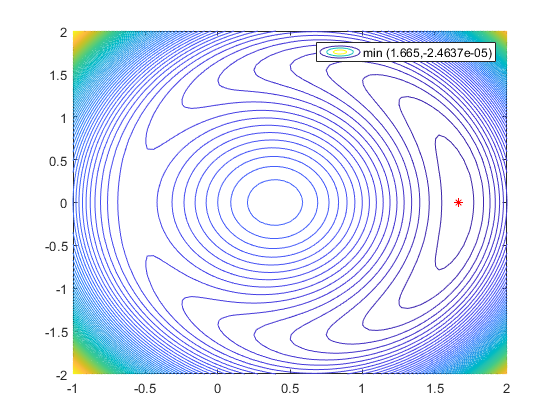

fcontour(f,[-1 2 -2 2],"LevelStep",0.5)
hold on
leg = [];
le = [leg "curve di livello"];
F = @(x) f(x(1),x(2));
[sol,fval]=fminsearch(F,[1.5; 0.5]);
plot(sol(1),sol(2),'*r')
leg =[leg "min ("+sol(1)+","+sol(2)+")"];
legend(leg)
hold off

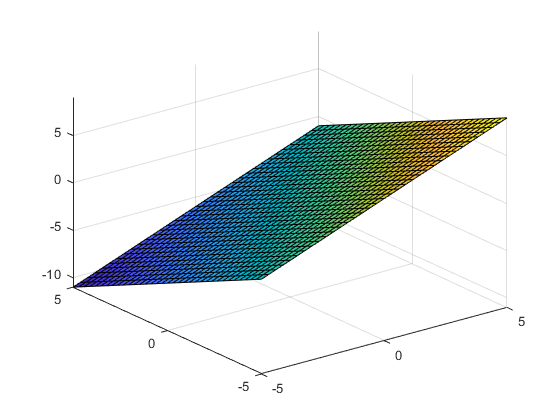


g = @(x,y) x-y-1;
fsurf(g)

fcontour(f,[-1 2 -2 2],"LevelStep",0.5)
hold on
leg = [];
leg = [leg "curve di livello"];

 y+x^2=< 0

A=[1 -1];b=0;
[sol,fval]=fmincon(F,[1.5;0.5],A,b);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


plot(sol(1),sol(2),'*r')
leg =[leg "min ("+sol(1)+","+sol(2)+")"];
fimplicit(g,[[-1,2] [-2 2]])
leg =[leg "g"];
legend(leg)

# metodo con funzione

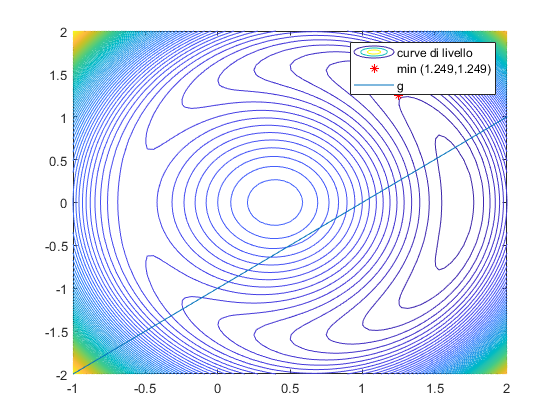

hold off

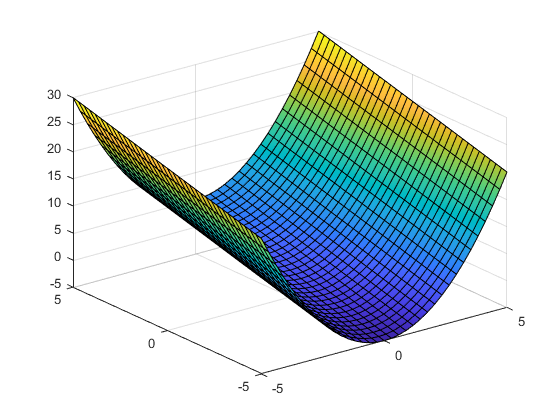

g = @(x,y) y+x.^2;
fsurf(g)

fcontour(f,[-1 2 -2 2],"LevelStep",0.5)
hold on
leg = [];
leg = [leg "curve di livello"];

y-x^2<0


sol = fmincon(F,[1.5;0.5],[],[],[],[],[],[],@(x) limit(x))


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol =     1.1524
   -1.3279


plot(sol(1),sol(2),'*r')
leg =[leg "min ("+sol(1)+","+sol(2)+")"];
fimplicit(g,[[-1,2] [-2 2]])
leg =[leg "g"];
legend(leg)

# metodo con funzione 2

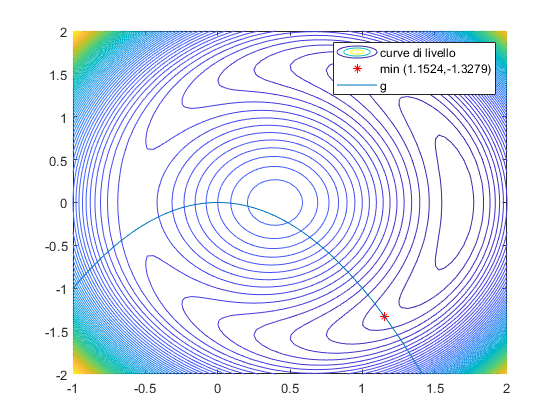

hold off

g = @(x,y) y+x.^2;
fsurf(g)

fcontour(f,[-1 2 -2 2],"LevelStep",0.5)
hold on
leg = [];
leg = [leg "curve di livello"];

y-x^2<0

limit2 = @(x) deal(g(x(1),x(2)),[]);
sol = fmincon(F,[1.5;0.5],[],[],[],[],[],[],limit2)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol =     1.1524
   -1.3279


plot(sol(1),sol(2),'*r')
leg =[leg "min ("+sol(1)+","+sol(2)+")"];
fimplicit(g,[[-1,2] [-2 2]])
leg =[leg "g"];
legend(leg)

function [C,Ceq] = limit(x)
C=x(2)+x(1)^2;
Ceq=[];
end